p1 = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
theta = rand*2*pi-pi

theta = -0.0103


p2 = rot(k,theta)*p1;

subproblem1(p1,p2,k)

ans = -0.0103

subproblem1_linear(p1,p2,k)

ans = -0.0103


N_trials = 10000

N_trials = 10000

N_attempts = 100

N_attempts = 100

T_orig = [];
T_linear = [];

for i = 1:N_trials
    p1 = rand([3 1])*10;
    k = rand([3 1]);
    k = k/norm(k);
    theta = rand*2*pi-pi;
    
    p2 = rot(k,theta)*p1;
    
    tic
    for j = 1:N_attempts
    s = subproblem1(p1,p2,k);
    end
    t = toc;
    T_orig = [T_orig t/N_attempts];

    tic
    for j = 1:N_attempts
    s= subproblem1_linear(p1,p2,k);
    end
    t = toc;
    T_linear = [T_linear t/N_attempts];
end

mean(T_orig)

ans = 2.6483e-06

mean(T_linear)

ans = 1.8080e-06


mean(T_orig)/mean(T_linear)

ans = 1.4648

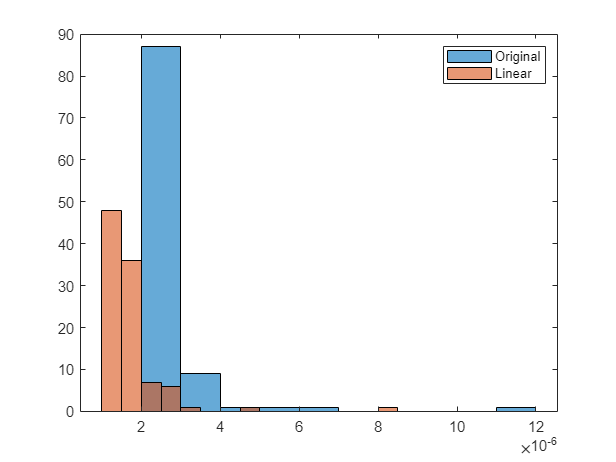


histogram(T_orig); hold on
histogram(T_linear); hold off
legend("Original", "Linear")